# Tarea: Regresión logística

### Aprendizaje computacional

### Juan Uriel Legaria Peña

### 0.- Explicación de la implementación

Las clases que componen a nuestra programa son las que se describen a continuación:

- DataPrecook: fue la clase implementada para llevar a cabo las tareas de preprocesamiento de datos que se requirieran. En este caso se utilizaron tres métodos: splitData para dividir en datos de entrenamiento y validación, encodeTwoClasses para asignar valores numéricos 0 y 1 a las etiquetas de hombre y mujer, y convertToMKS, el cual hace conversiones de unidades al sistema internacional. Este último se requirió ya que los datos de masa y altura venían respectivamente en libras y pulgadas.

- LogisticRegressionFit: Es la clase que lleva a cabo el ajuste de un modelo de regresión logística a los datos.   Aquí se implementaron las 3 formas de entrenamiento vistas en clase: descenso del gradiente, descenso del gradiente estocástico y mini batch.

### 1.- Regresión de los datos

#### 1.1.- Lectura y preparación de los datos.

%Leemos los datos
T = readtable('weight-height.csv', 'PreserveVariableNames',true);
%Extraemos las diferentes columnas
genderTags = T{:,1};
heightInches = T{:,2};
weightPounds = T{:,3};
%Convertimos a 0 y 1 las etiquetas de las dos clases
cooker = DataPrecook();
enumeratedGender = cooker.enumerateClasses(["Male","Female"],genderTags);
%Convertimos a sistema SI los datos de peso y estatura
heightMeters = cooker.convertUnits(Unit.INCHES, Unit.METERS, heightInches);
weightKilos = cooker.convertUnits(Unit.POUND, Unit.KILOGRAM, weightPounds);
%Combinamos los datos de peso y estatura en una sola tabla
X = [heightMeters'; weightKilos'];
[trainingData, trainingDataResults, validationData, validationDataResults] = cooker.splitData(X,enumeratedGender',0.25);

#### 1.2.- Entrenamiento por descenso del gradiente

%Entrenamos
gradientFit = LogisticRegressionFit(trainingData, trainingDataResults, validationData, validationDataResults);
epochs = 5000;
learningRate = 0.001;
gradientFit = gradientFit.trainByGradientDescent(epochs, learningRate);

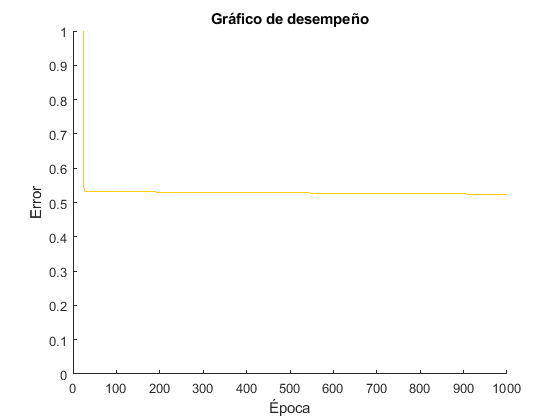

%Gráfico de desempeño del entrenamiento
figure()
hold on 
title("Gráfico de desempeño")
plot(1:epochs, abs(gradientFit.validationPerformance),'Color','#ffc917')
ylabel('Error')
xlabel('Época')
ylim([0,1])
hold off

disp(gradientFit.beta)

    1.0421    1.0472   -0.0415



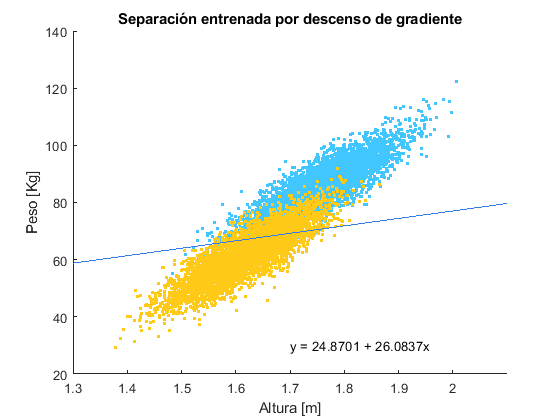

%Gráfico de separación de puntos
beta = gradientFit.beta;
xInterval = linspace(1.3,2.1,1000);
p = 0.5;
d = log(p/(1-p));
y = -(d/beta(3)) - beta(1)/beta(3) - (beta(2)/beta(3))*xInterval;
figure()
hold on 
title("Separación entrenada por descenso de gradiente")
for i = 1:size(X,2)
    yValue= enumeratedGender(i);
    if(yValue == 0)
        plot(X(1,i),X(2,i),'Color','#42c6ff','Marker','o','LineStyle','None','MarkerSize',2,'MarkerFaceColor','#42c6ff')
    else
        plot(X(1,i),X(2,i),'Color','#ffc917','Marker','o','LineStyle','None','MarkerSize',2,'MarkerFaceColor','#ffc917')
    end
end
plot(xInterval, y,'Color', '#347deb')
xlabel('Altura [m]')
ylabel('Peso [Kg]')
text(1.7, 30, strcat( "y = ",string(-beta(1)/beta(3))," + ",string(-beta(2)/beta(3)),"x"))
hold off

gradientFit.getContingencyTable()

ans = 1×7 table
    VP     FP    FN      VN     sensibilidad    Especificidad    Accuracy
    ___    __    ___    ____    ____________    _____________    ________

    974    32    276    1218       0.7792          0.9744         0.8768 


**1.2.- Entrenamiento por descenso del gradiente estocástico**

stochasticFit = LogisticRegressionFit(trainingData, trainingDataResults, validationData, validationDataResults);
epochs = 10000;
learningRate = 0.0001;
stochasticFit = stochasticFit.trainByStochasticGradientDescent(epochs, learningRate);

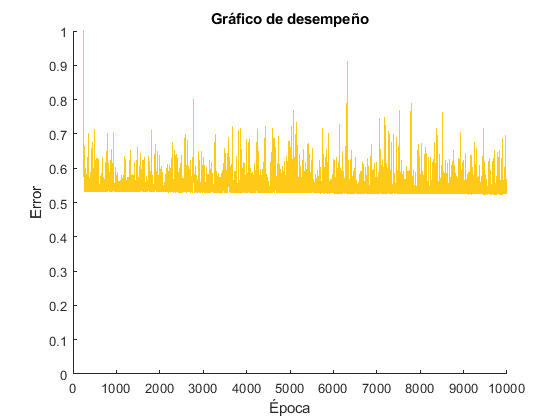

%Gráfico de desempeño del entrenamiento
figure()
hold on 
title("Gráfico de desempeño")
plot(1:epochs, abs(stochasticFit.validationPerformance),'Color','#ffc917')
ylabel('Error')
xlabel('Época')
ylim([0,1])
hold off

disp(stochasticFit.beta)

    1.0429    1.0481   -0.0383



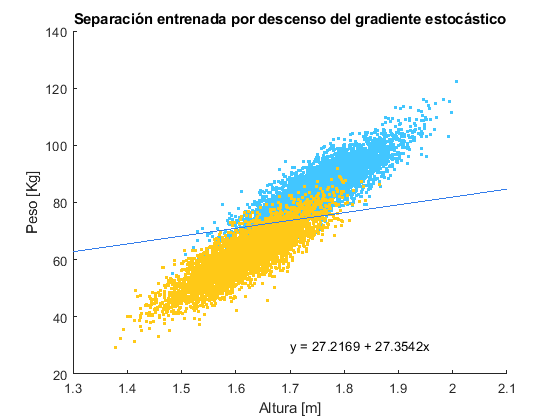

beta = stochasticFit.beta;
xInterval = linspace(1.3,2.1,1000);
p = 0.5;
d = log(p/(1-p));
y = -(d/beta(3)) - beta(1)/beta(3) - (beta(2)/beta(3))*xInterval;
figure()
hold on 
title("Separación entrenada por descenso del gradiente estocástico")
for i = 1:size(X,2)
    yValue= enumeratedGender(i);
    if(yValue == 0)
        plot(X(1,i),X(2,i),'Color','#42c6ff','Marker','o','LineStyle','None','MarkerSize',2,'MarkerFaceColor','#42c6ff')
    else
        plot(X(1,i),X(2,i),'Color','#ffc917','Marker','o','LineStyle','None','MarkerSize',2,'MarkerFaceColor','#ffc917')
    end
end
plot(xInterval, y,'Color', '#347deb')
xlabel('Altura [m]')
ylabel('Peso [Kg]')
text(1.7, 30, strcat( "y = ",string(-beta(1)/beta(3))," + ",string(-beta(2)/beta(3)),"x" + ...
    ""))
hold off

stochasticFit.getContingencyTable()

ans = 1×7 table
     VP     FP     FN      VN     sensibilidad    Especificidad    Accuracy
    ____    ___    ___    ____    ____________    _____________    ________

    1147    109    103    1141       0.9176          0.9128         0.9152 


#### 1.3.- Mini-Batch

batchFit = LogisticRegressionFit(trainingData, trainingDataResults, validationData, validationDataResults);
epochs = 10000;
learningRate = 0.0001;
minibatchSize = 10;
batchFit = batchFit.trainByMinibatch(epochs, learningRate,minibatchSize);

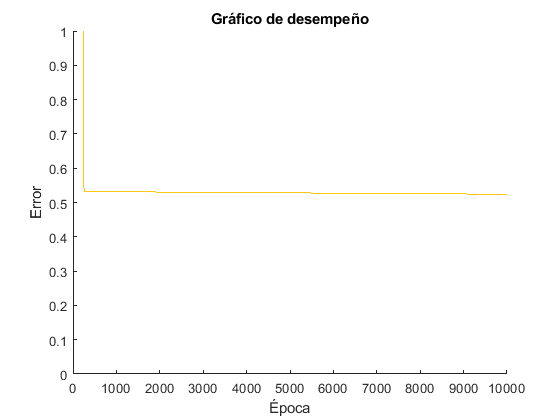

%Gráfico de desempeño del entrenamiento
figure()
hold on 
title("Gráfico de desempeño")
plot(1:epochs, abs(batchFit.validationPerformance),'Color','#ffc917')
ylabel('Error')
xlabel('Época')
ylim([0,1])
hold off

disp(batchFit.beta)

    1.0421    1.0472   -0.0416



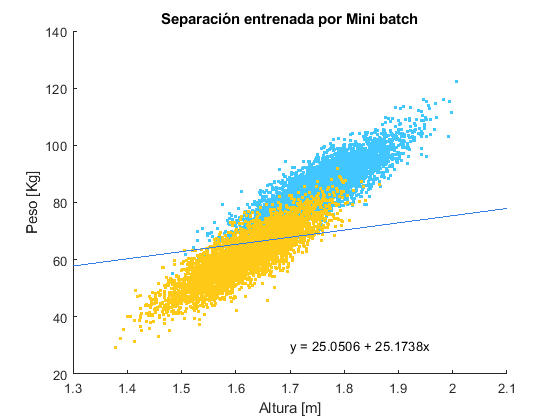

beta = batchFit.beta;
xInterval = linspace(1.3,2.1,1000);
p = 0.5;
d = log(p/(1-p));
y = -(d/beta(3)) - beta(1)/beta(3) - (beta(2)/beta(3))*xInterval;
figure()
hold on 
title("Separación entrenada por Mini batch")
for i = 1:size(X,2)
    yValue= enumeratedGender(i);
    if(yValue == 0)
        plot(X(1,i),X(2,i),'Color','#42c6ff','Marker','o','LineStyle','None','MarkerSize',2,'MarkerFaceColor','#42c6ff')
    else
        plot(X(1,i),X(2,i),'Color','#ffc917','Marker','o','LineStyle','None','MarkerSize',2,'MarkerFaceColor','#ffc917')
    end
end
plot(xInterval, y,'Color', '#347deb')
xlabel('Altura [m]')
ylabel('Peso [Kg]')
text(1.7, 30, strcat( "y = ",string(-beta(1)/beta(3))," + ",string(-beta(2)/beta(3)),"x" + ...
    ""))
hold off

batchFit.getContingencyTable()

ans = 1×7 table
    VP     FP    FN      VN     sensibilidad    Especificidad    Accuracy
    ___    __    ___    ____    ____________    _____________    ________

    890    23    360    1227       0.712           0.9816         0.8468 


### 2.- Observaciones

De las figuras anteriores es posible apreciar que se consiguen resultados similares para la separación de datos con los 3 métodos de entrenamiento examinados. Hay sin embargo pequeñas diferencias notorias que se hacen presentes sobre todo en los gráficos de desempeño. Particularmente en el caso estocástico el error tiende a variar alrededor del valor estacionario, este es un efecto que como se vio en clase puede disminuirse jugando un poco con el factor de entrenamiento, una mejora posible sería por ejemplo hacer que este disminuya conforme transcurren las épocas. En este caso particular sin embargo, estas oscilaciones terminaron ayudando a mejorar el accuracy conseguido (0.91); podríamos decir que corrimos con suerte, en el sentido estadístico de la palabra.  

Un aspecto importante de lo visto en clase que pude experimentar con este ejemplo, fue la sugerencia que se nos hizo de intentar mantener todo constante al variar algún parámetro del modelo como serían las épocas o el factor de aprendizaje. En un principio tenia demasiadas fuentes de aleatoriedad como la inicialización aleatoria de los parámetros $\beta \;$, o el usar distintos datos de entrenamiento y validación para los diferentes entrenamientos. Esto hacia que se obtuvieran modelos muy diferentes de una corrida a otra, por lo cual tuve que controlar mejor esas fuentes de variación. Las medidas que tomé fueron 2: Inicializar a un valor constante de 1 todos los parámetros del modelo y establecer la división entre datos de entrenamiento y validación desde un inicio y usar esos mismos arreglos para los diferentes tipos de entrenamiento que probé. 

Es interesante que la convergencia del modelo sea muy sensible al valor inicial de los parámetros $\beta \;$. A pesar de la suavización del logaritmo parece haber bastantes mínimos locales a los que puede caer el sistema con estos datos. Creo que aquí estaríamos en presencia de una situación que se nos había comentado, donde el rendimiento del modelo a utilizar dependerá mucho de que se introduzcan datos o características que "se acoplen" en cierto modo a la estructura del modelo.